clear

addpath("matlab_functions\")

#### Add defect to plate

Model = myModel;
freqs = [100]; % (Hz)
mesh_size = 4; % 1:finest 9:coarsest

global defects
defects = {};

Model = ComsolInterface('Build', Model);

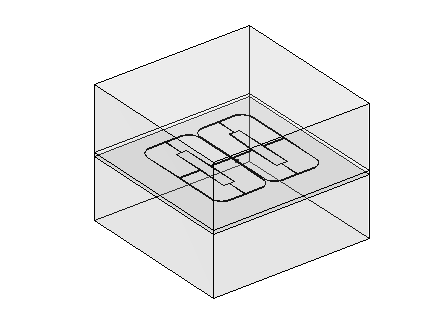


% ComsolInterface('AddRectangularDefect', Model, 0, 0, 8e-3, 0.5e-3, 0, -3e-3)
ComsolInterface('AddCircularDefect',    Model, 5e-3, 0, 2e-3,       0, -2e-3)

figure
ComsolInterface('PlotGeometry', Model)

#### Compute fields

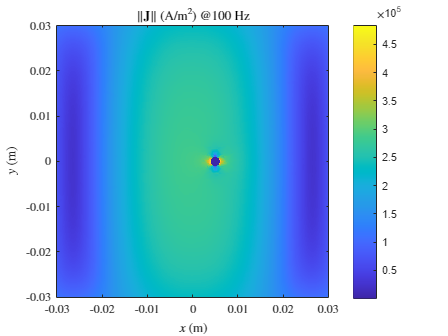

x = Model.sensors.positions(1,:);
y = Model.sensors.positions(2,:);
z = Model.sensors.positions(3,:);
B_data = zeros(length(freqs), length(x));

for i = 1:length(freqs)
    ComsolInterface('EnableMaterial', Model, true);
    ComsolInterface('Solve', Model, freqs(i), mesh_size);
    [Bx,By,Bz] = ComsolInterface('InterpField', Model, {'Bx' 'By' 'Bz'}, x,y,z);
    B_data(i,:) = dot([Bx;By;Bz], Model.sensors.axes);    

    x_ = linspace(-30e-3, 30e-3, 500);
    [x_,y_,z_] = ndgrid(x_, x_, -0.5e-3);    
    normJ = ComsolInterface('InterpField', Model, 'normJ', x_,y_,z_);
    
    figure
    imagesc([min(x_,[],'all') max(x_,[],'all')],[min(y_,[],'all') max(y_,[],'all')], normJ.')
    colorbar
    axis square xy
    xlabel('$x$ (m)', 'Interpreter','latex')
    ylabel('$y$ (m)', 'Interpreter','latex')
    title(strcat('$\|\textbf{J}\|$ (A/m$^2$) @ ',string(freqs(i)),' Hz'), 'Interpreter','latex')

    ComsolInterface('EnableMaterial', Model, false);
    ComsolInterface('Solve', Model, freqs(i), mesh_size);
    [Bx,By,Bz] = ComsolInterface('InterpField', Model, {'Bx' 'By' 'Bz'}, x,y,z);
    B_data(i,:) = B_data(i,:) - dot([Bx;By;Bz], Model.sensors.axes);
end


clear x y z i Bx By Bz lim x_ y_ z_ normJ

#### Export sensor data

fname = sprintf('data/B_ec_%s.txt', datetime('now','Format','MMdd-HHmm'));

fid = fopen(fname, 'w');

for i = 1:length(defects)
    fprintf(fid, '%% defect %s\n', jsonencode(defects{i}));
end
for i = 1:length(freqs)
    fprintf(fid, '%% frequency %g Hz\n', freqs(i));
    fprintf(fid, '%s\n', num2str(B_data(i,:)));
end

fclose(fid);

clear fname fid i